# Clover Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a few clover graphs.

## Set up the graph structure and coordinates of the problem

Use the template function to define the dumbbell quantum graph.

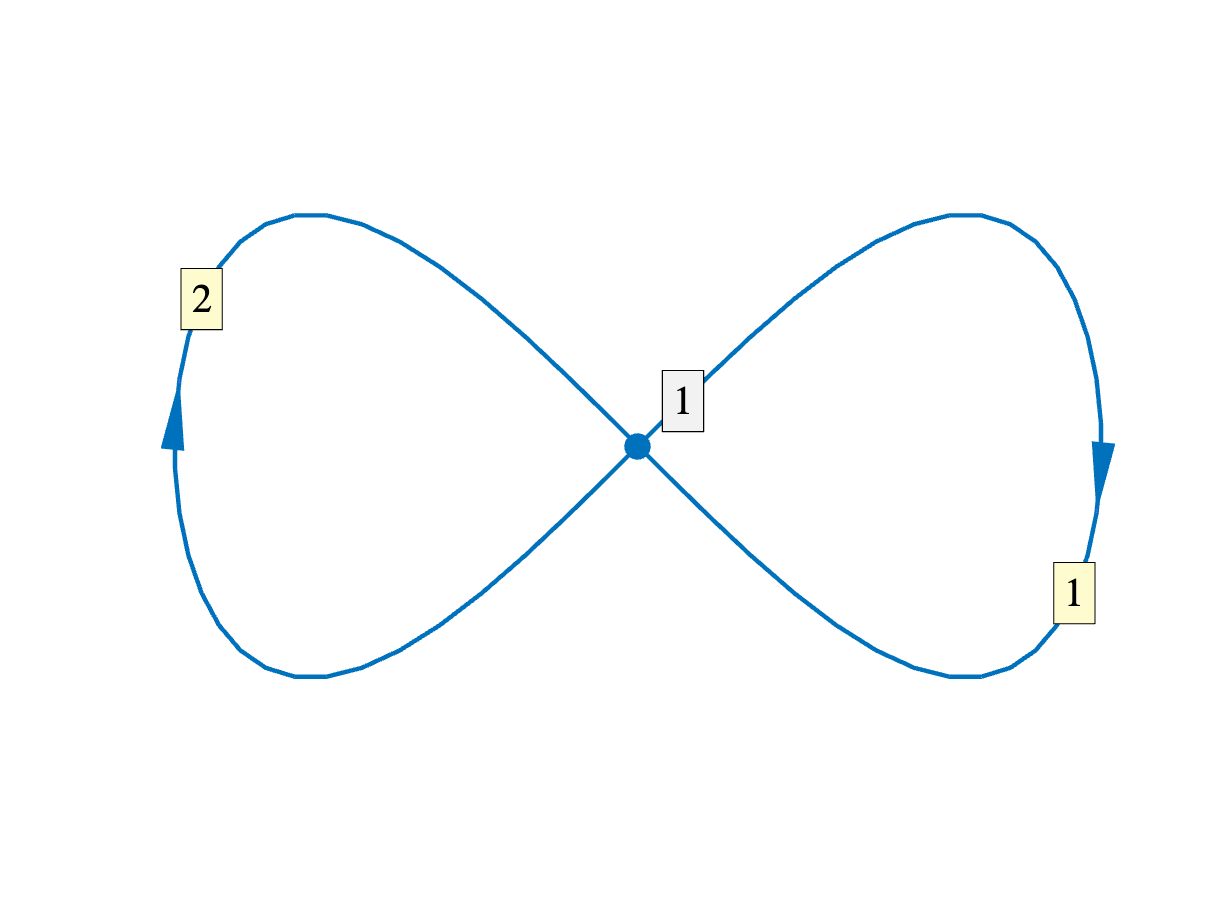

Phi = quantumGraphFromTemplate('clover','nleaves',2,'nx',32,'L',[pi pi]);
Phi.plot('layout')

The layout function is defined by the program `cloverPlotCoords` in the `templates` folder. 

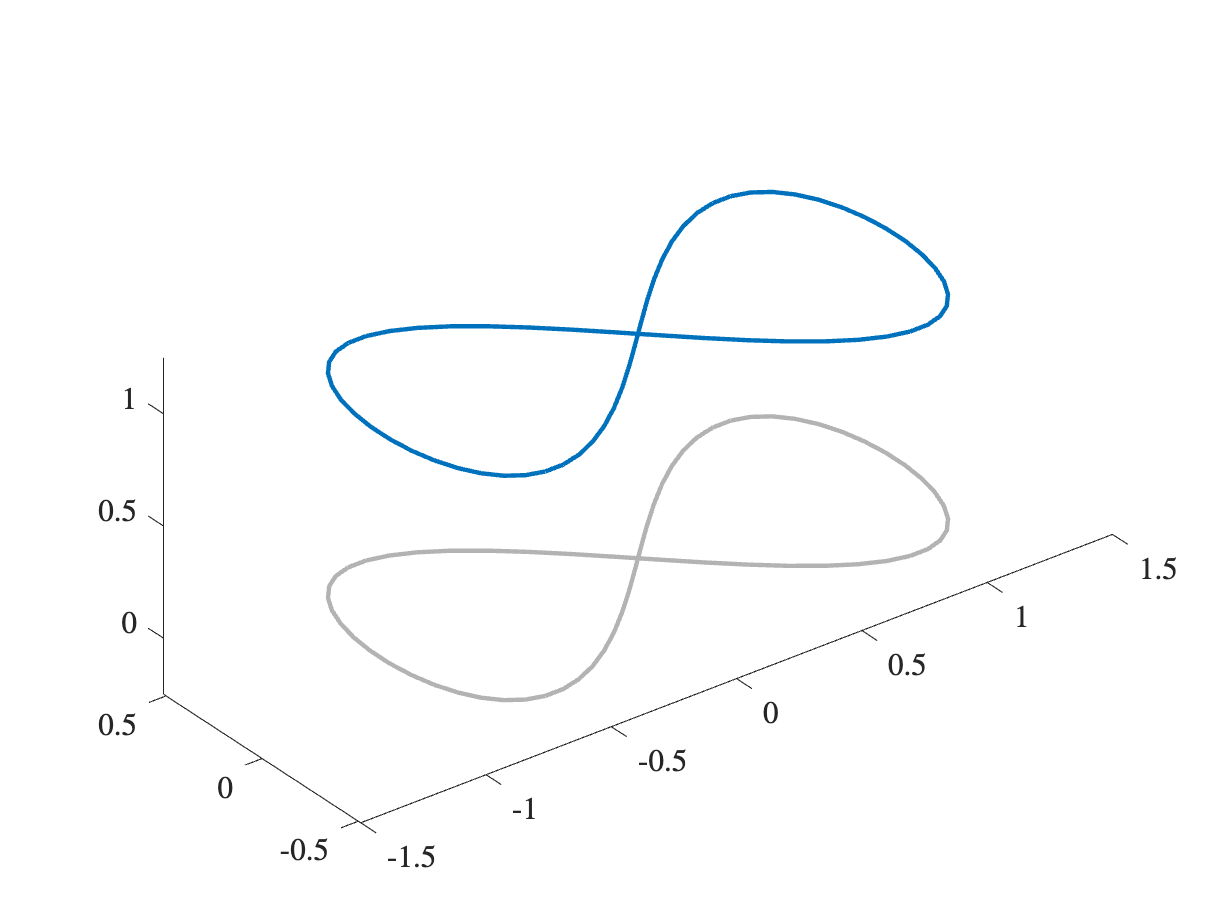

u0=Phi.applyFunctionsToAllEdges({1,1});
Phi.plot(u0);

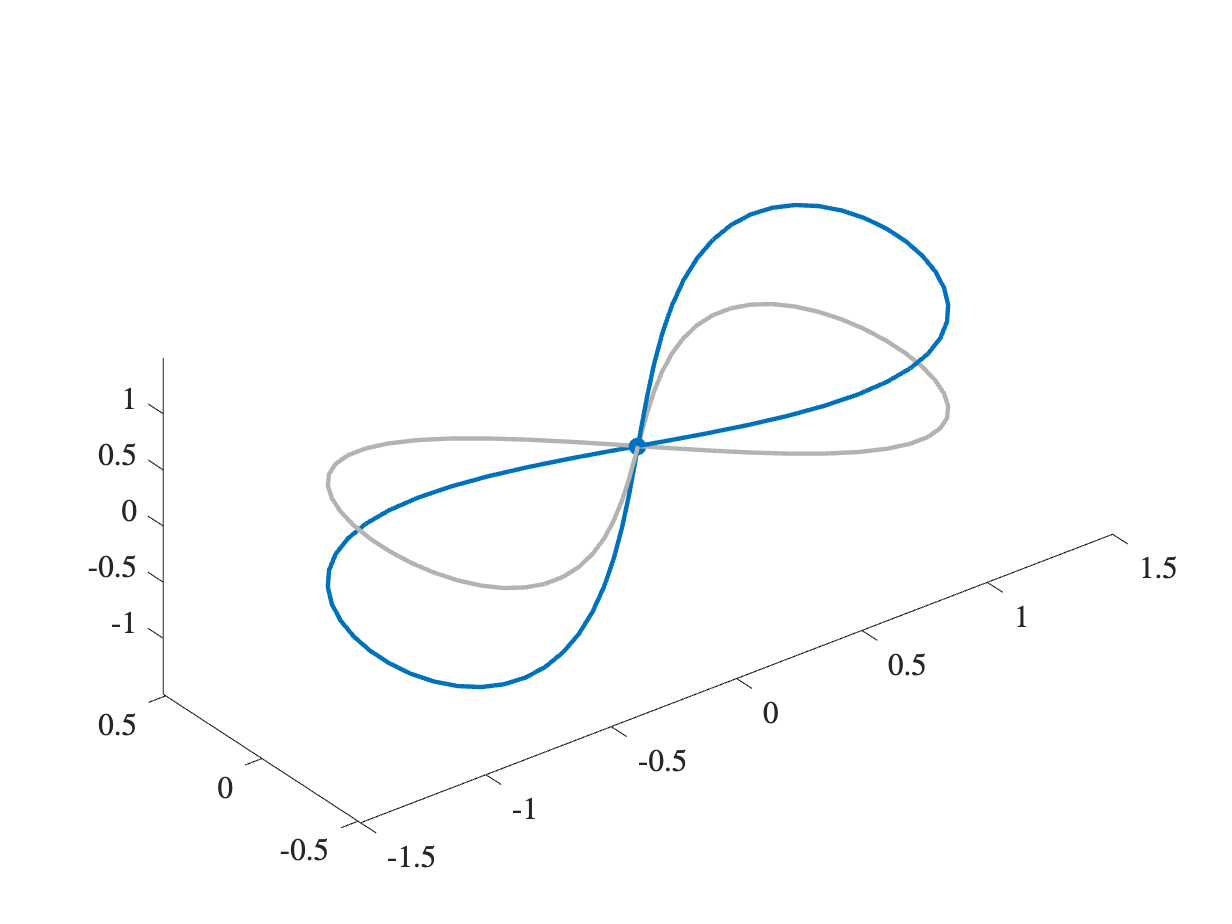

u=Phi.applyFunctionsToAllEdges({@(x)sin(x),@(x)-sin(x)});
Phi.plot(u)

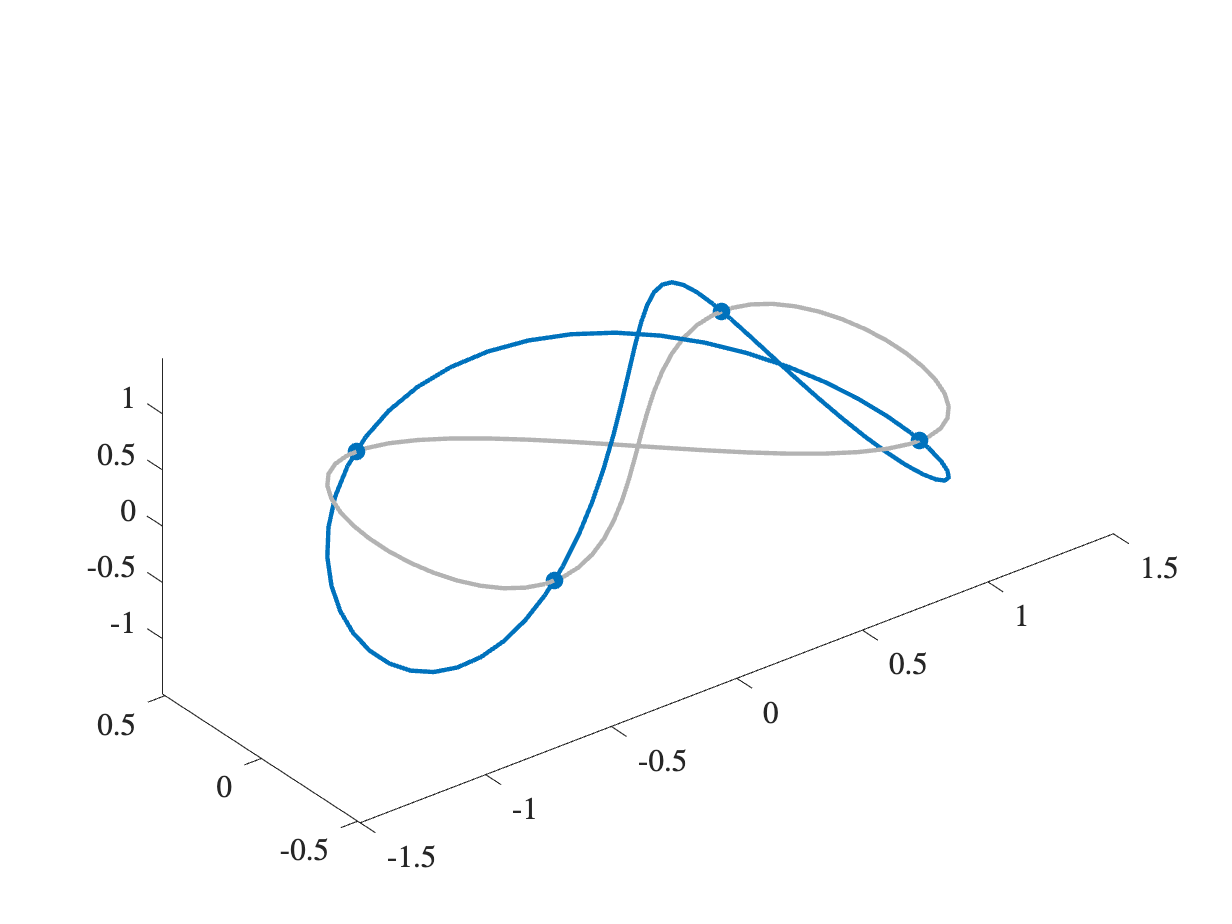

u=Phi.applyFunctionsToAllEdges({@(x)cos(2*x),@(x)cos(2*x)});
Phi.plot(u)

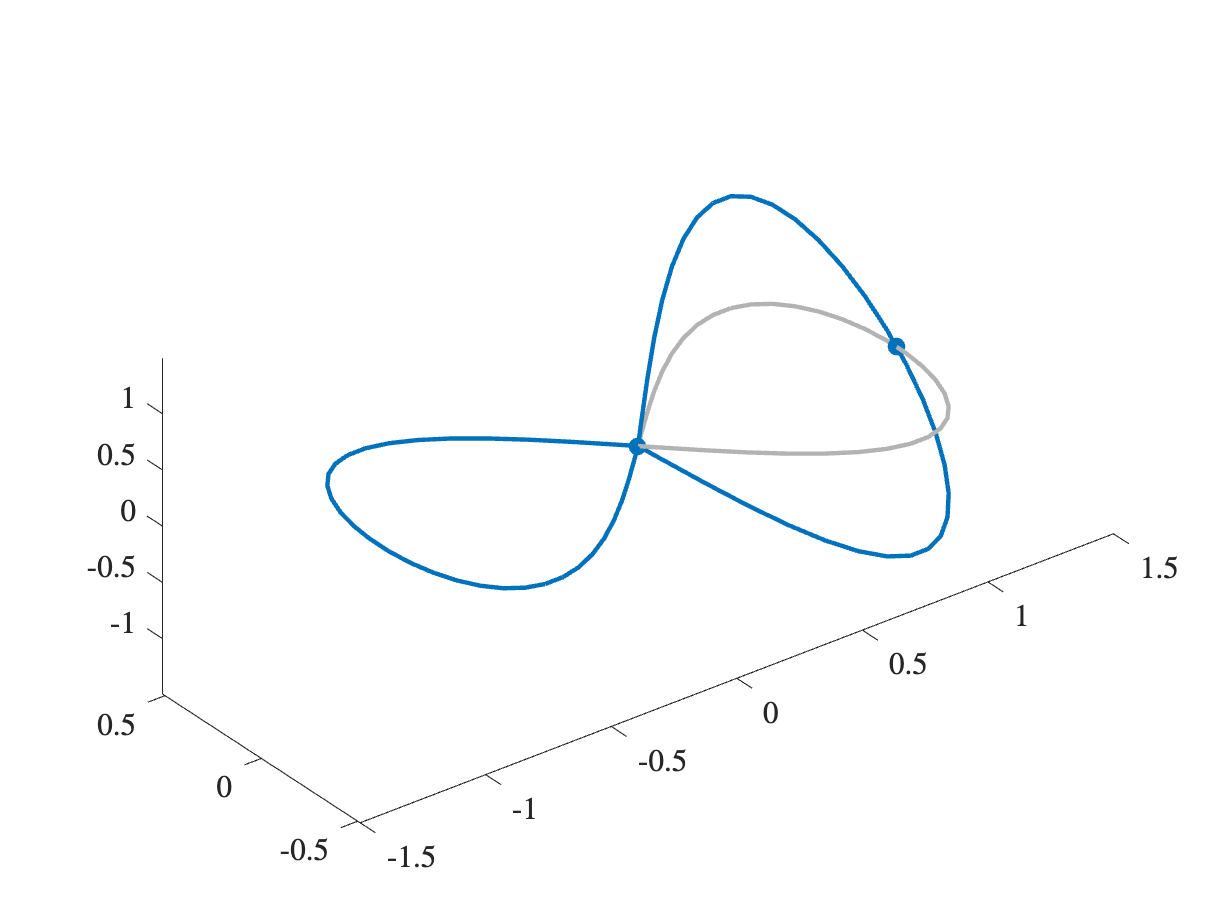

u=Phi.applyFunctionsToAllEdges({@(x)sin(2*x),0});
Phi.plot(u)

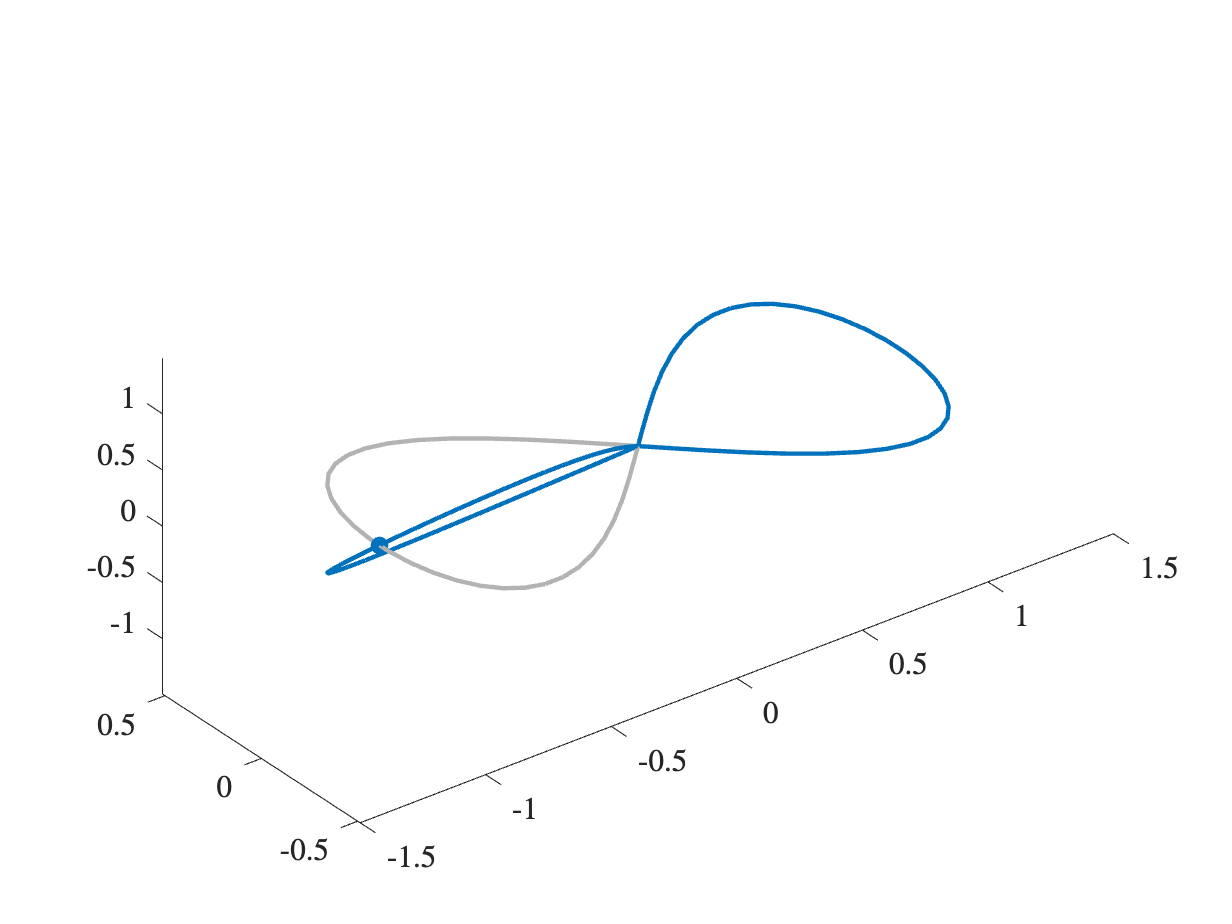

u=Phi.applyFunctionsToAllEdges({0,@(x)sin(2*x)});
Phi.plot(u)

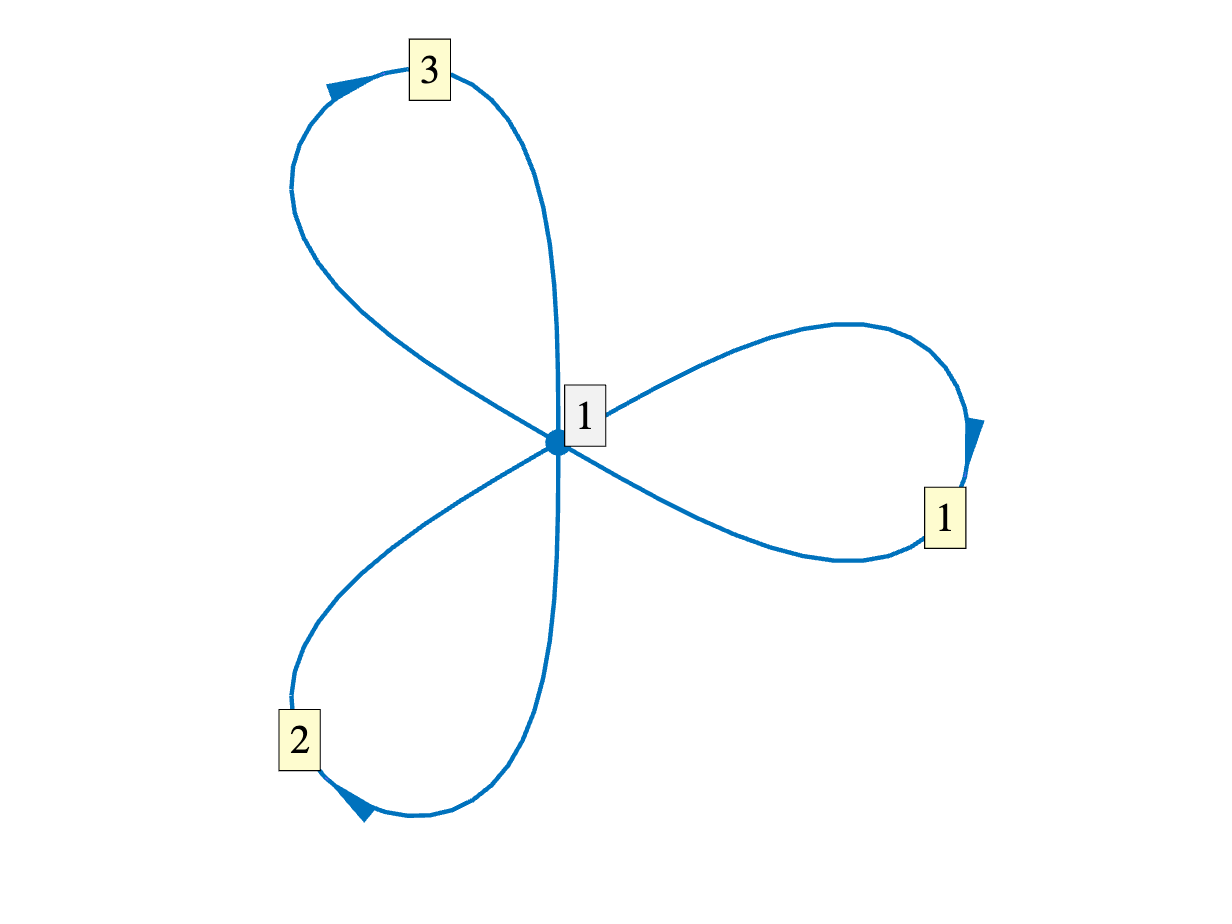

Phi = quantumGraphFromTemplate('clover','nleaves',3,'nx',32,'L',[pi pi pi]);
Phi.plot('layout')

The layout function is defined by the program `cloverPlotCoords` in the `templates` folder. 

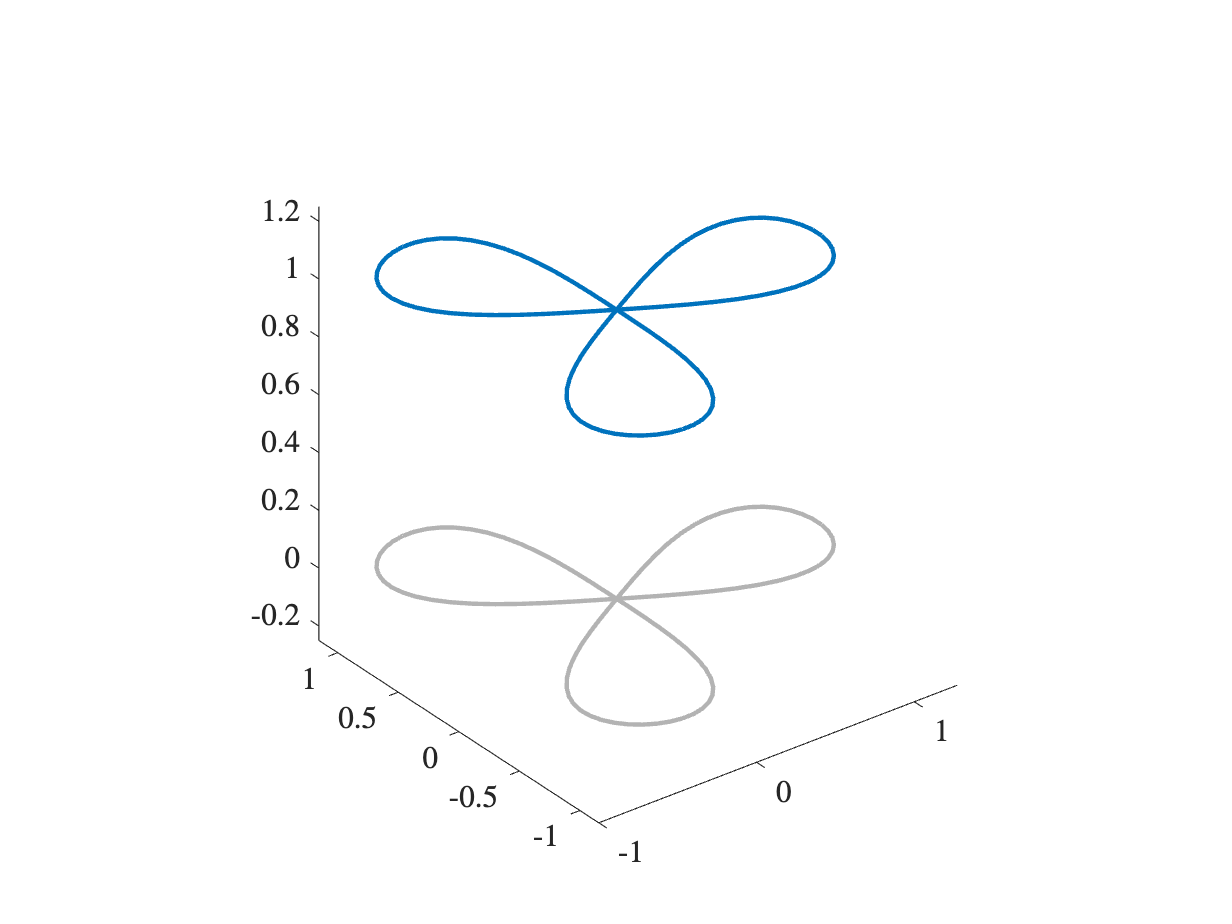

u0=Phi.applyFunctionsToAllEdges({1,1,1});
Phi.plot(u0);

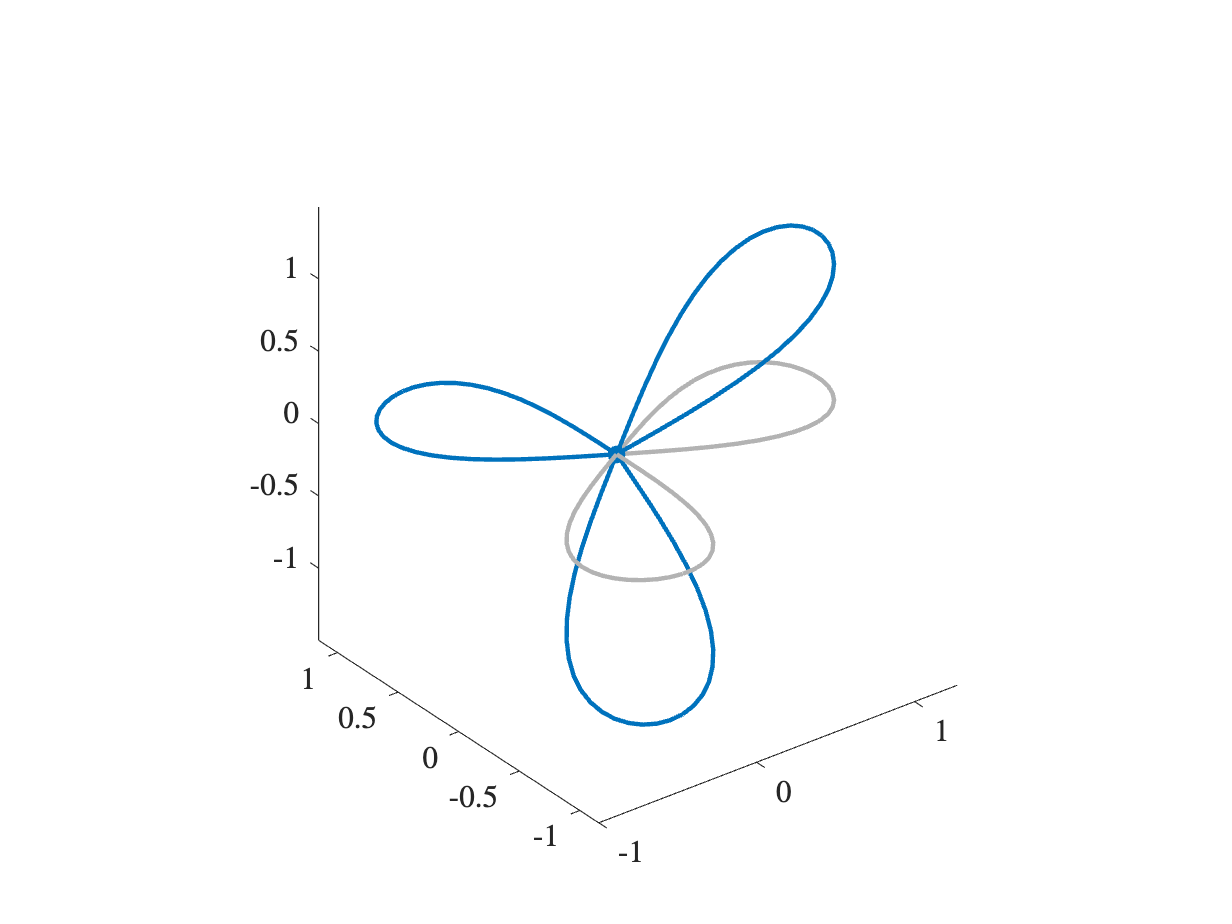

u=Phi.applyFunctionsToAllEdges({@(x)sin(x),@(x)-sin(x),0});
Phi.plot(u)

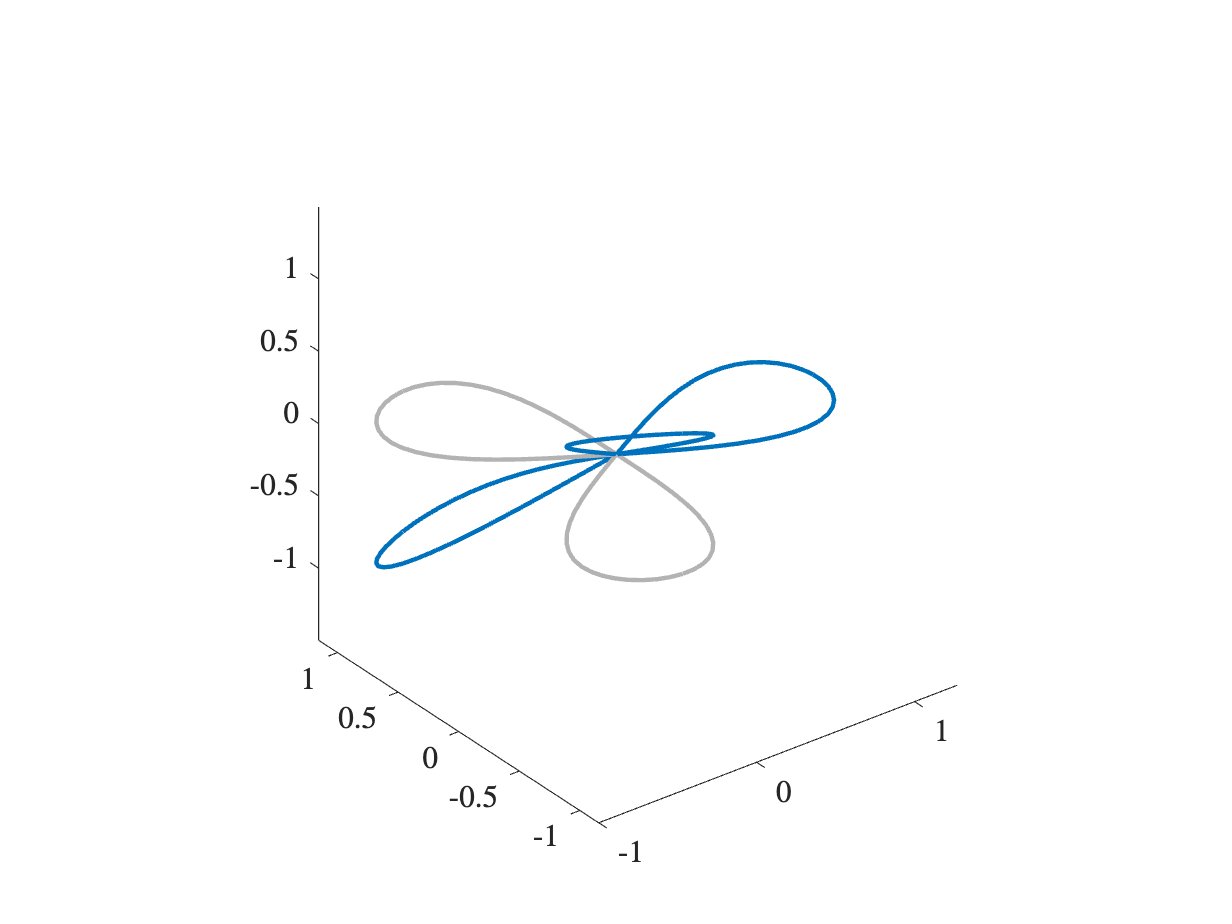

u=Phi.applyFunctionsToAllEdges({0,@(x)sin(x),@(x)-sin(x)});
Phi.plot(u)

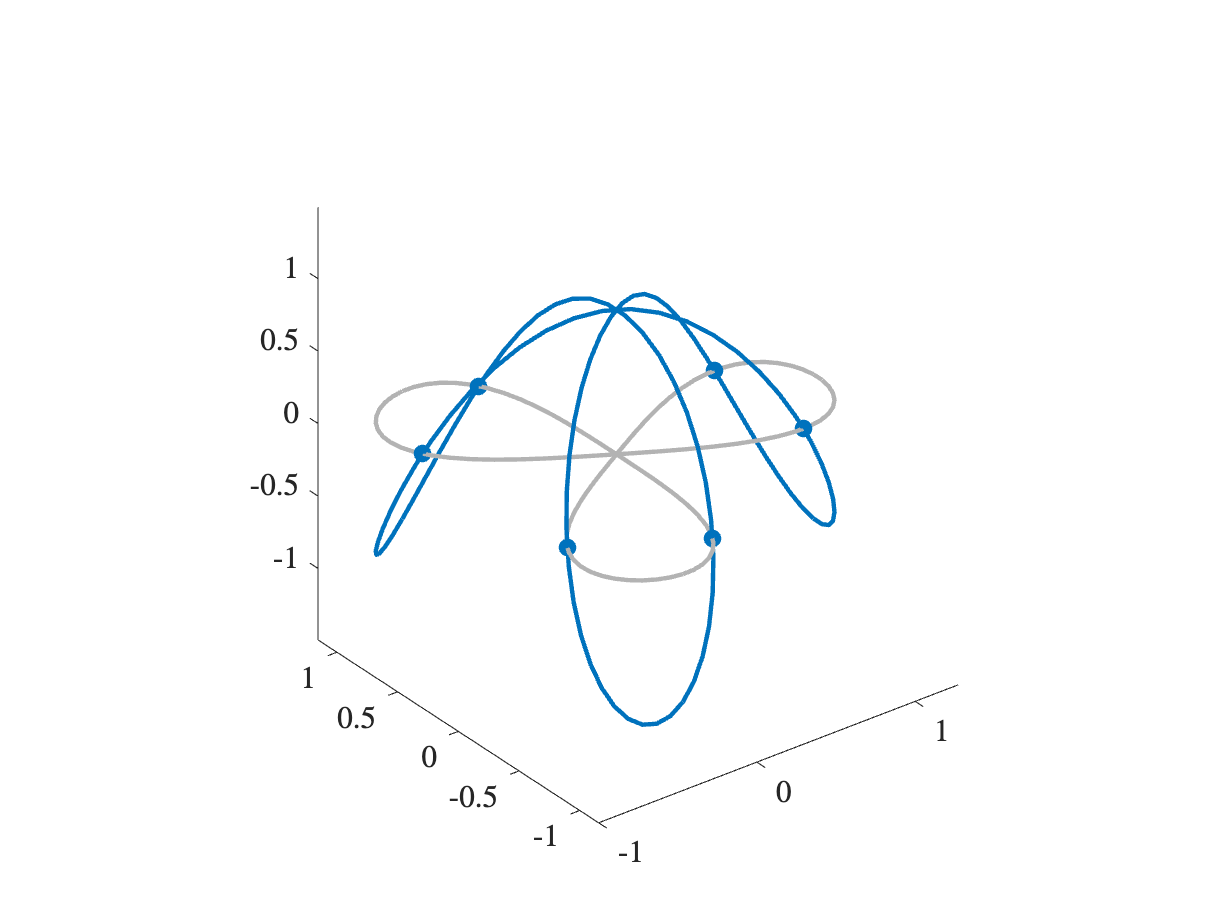

u=Phi.applyFunctionsToAllEdges({@(x)cos(2*x),@(x)cos(2*x),@(x)cos(2*x)});
Phi.plot(u)

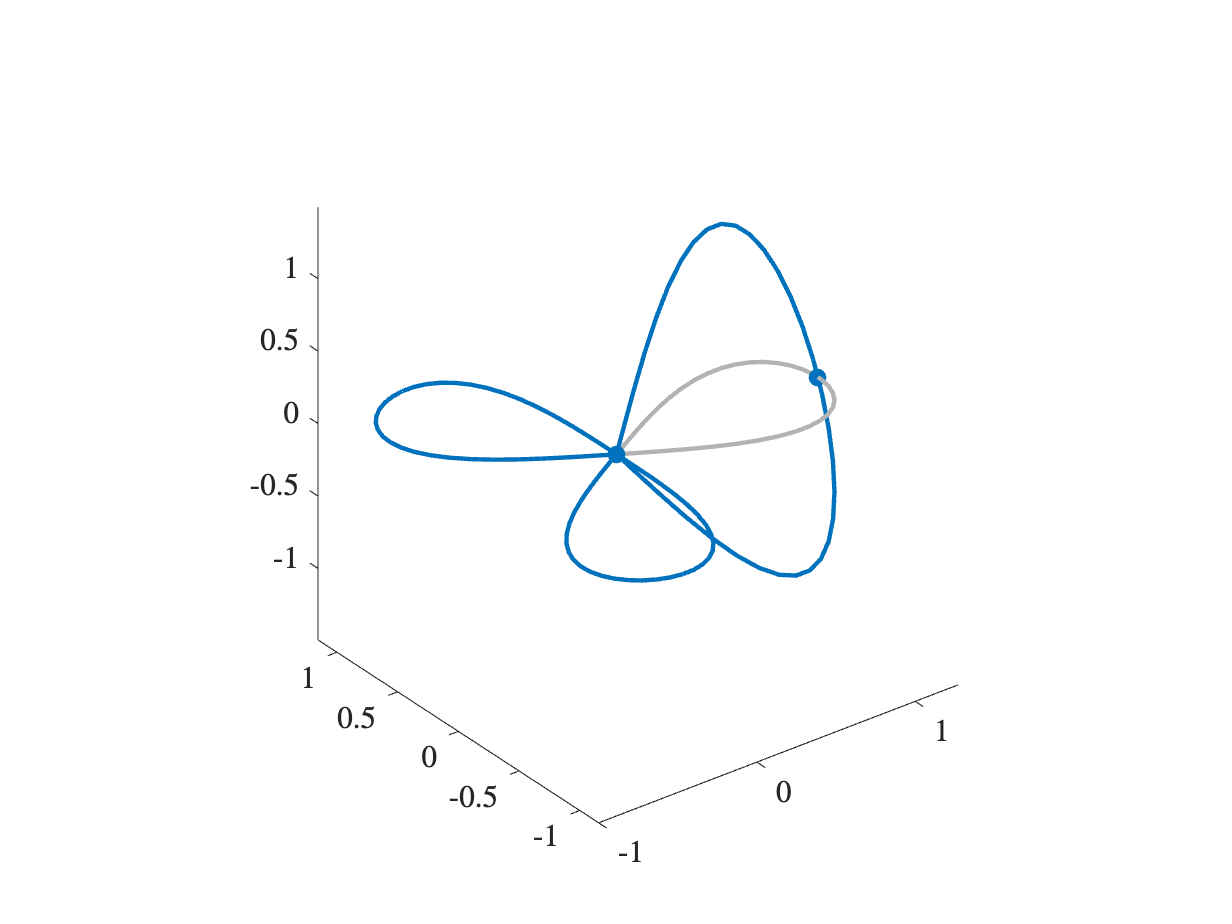

u=Phi.applyFunctionsToAllEdges({@(x)sin(2*x),0,0});
Phi.plot(u)

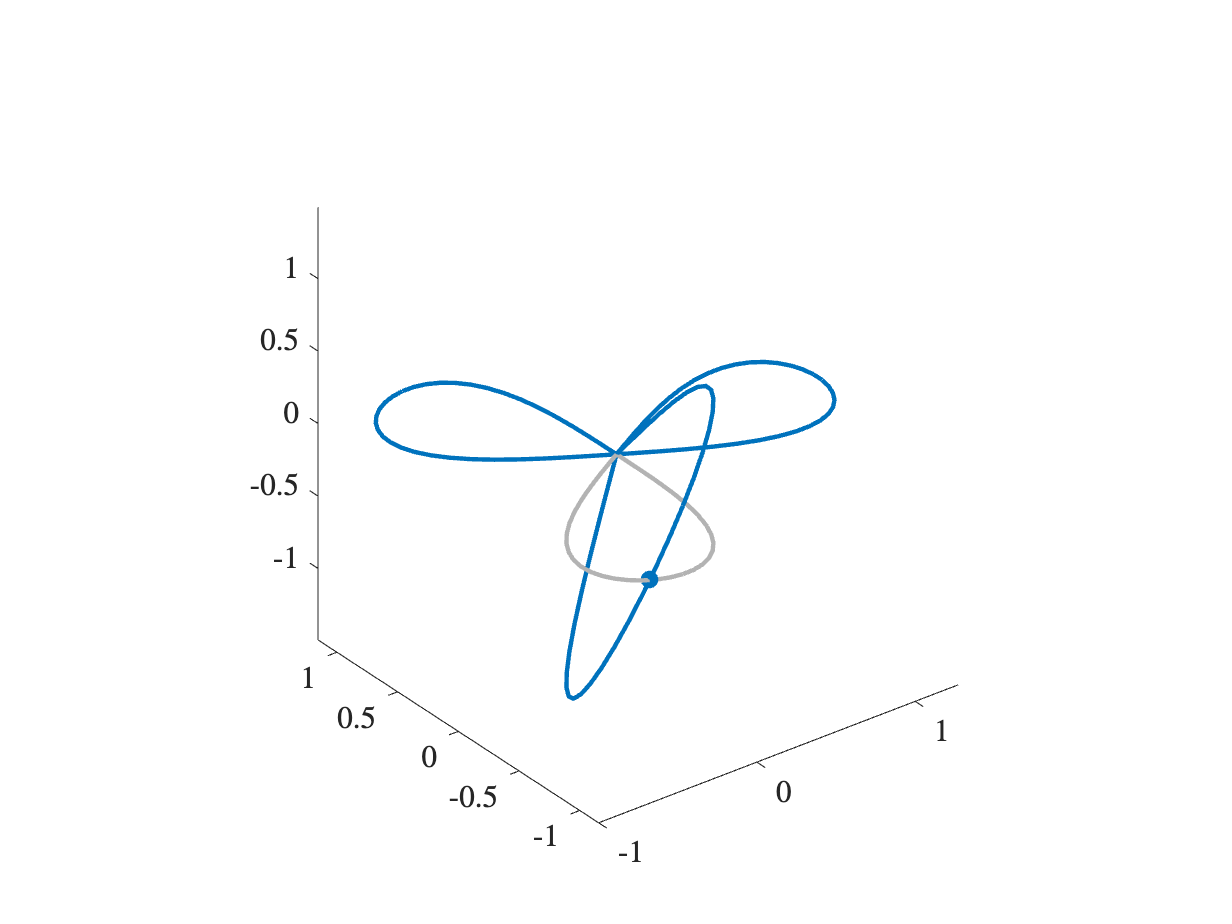

u=Phi.applyFunctionsToAllEdges({0,@(x)sin(2*x),0});
Phi.plot(u)

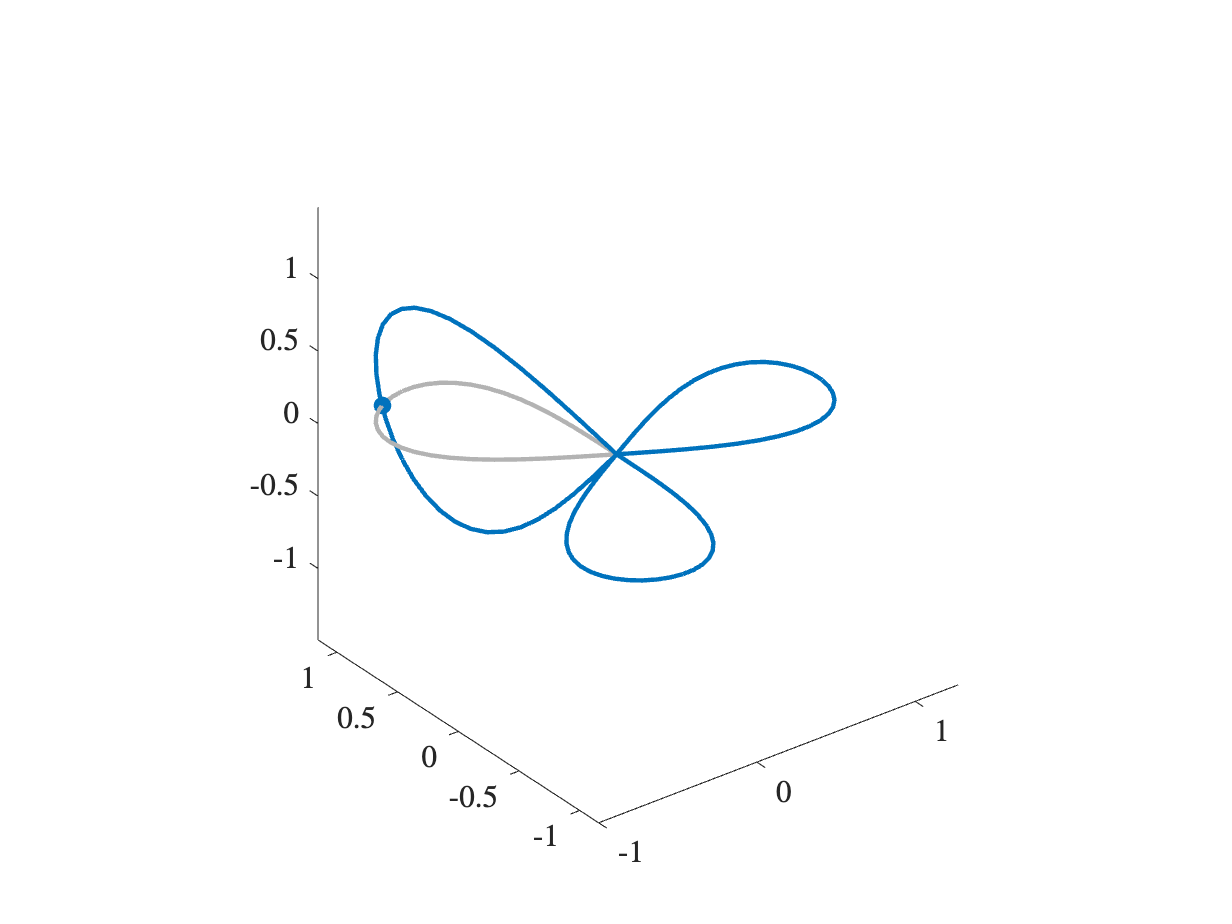

u=Phi.applyFunctionsToAllEdges({0,0,@(x)sin(2*x)});
Phi.plot(u)

### Toshi calls this the $\Theta$ graph, but I like to call it the pumpkin. I've also heard it called the mandarin

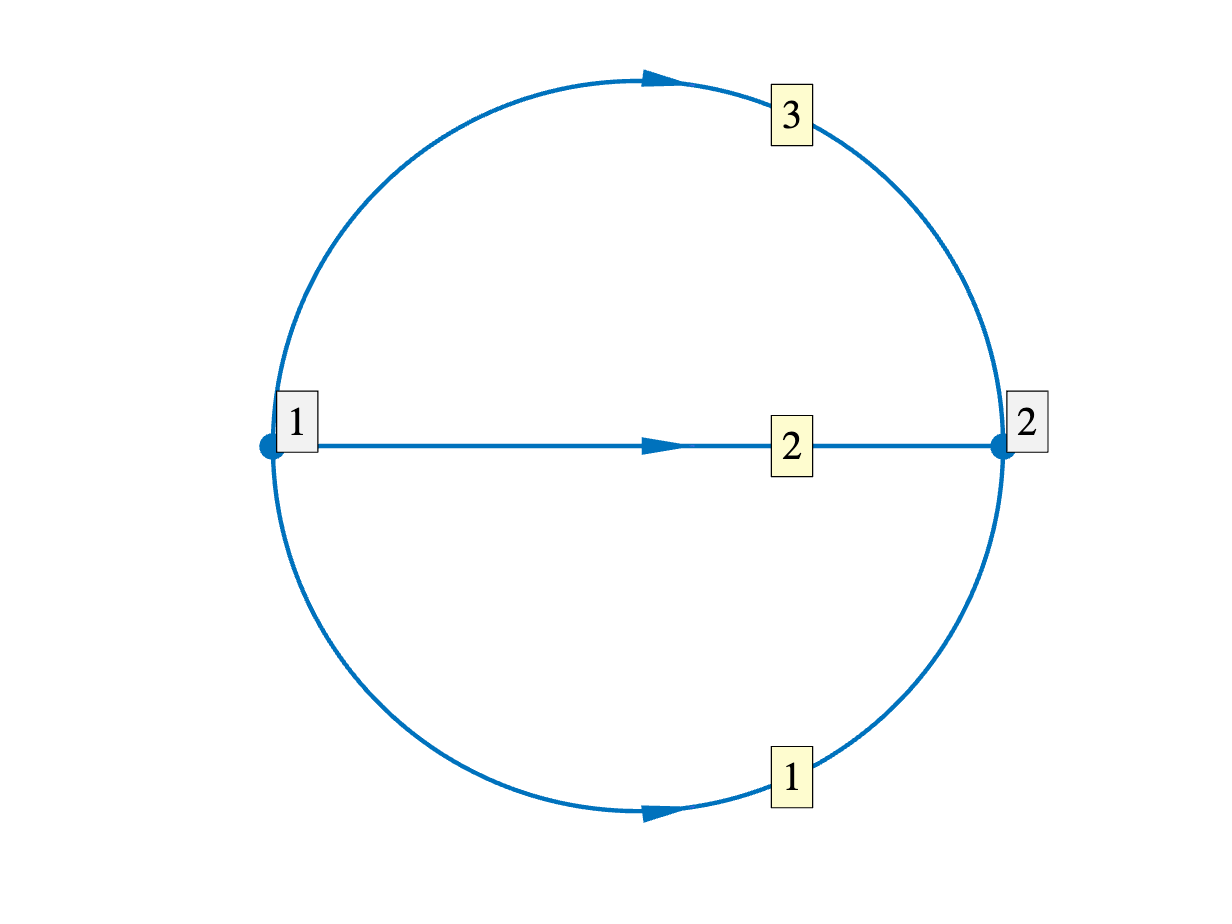

Phi=quantumGraphFromTemplate('pumpkin');
Phi.plot('layout');

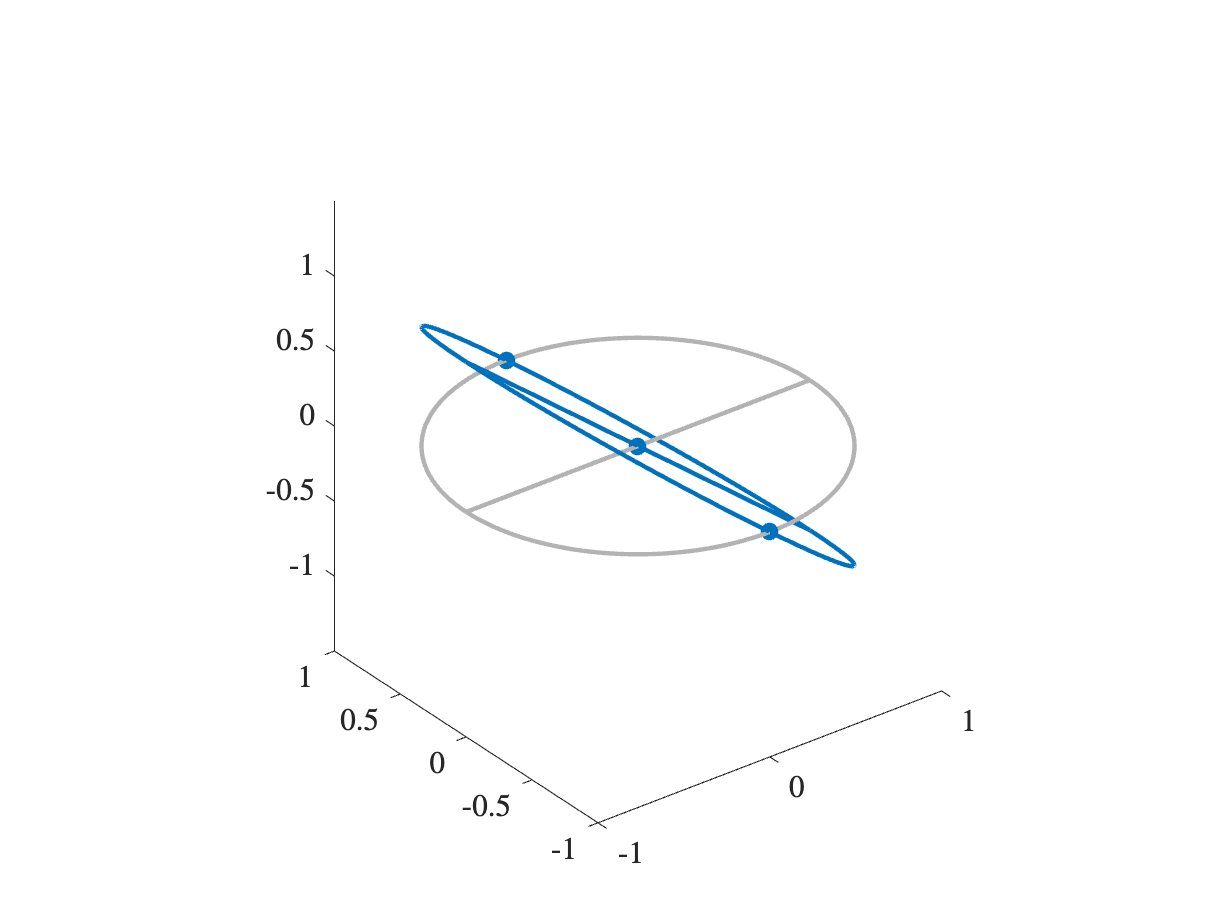

Phi.applyFunctionsToAllEdges({@cos,@cos,@cos})
Phi.plot

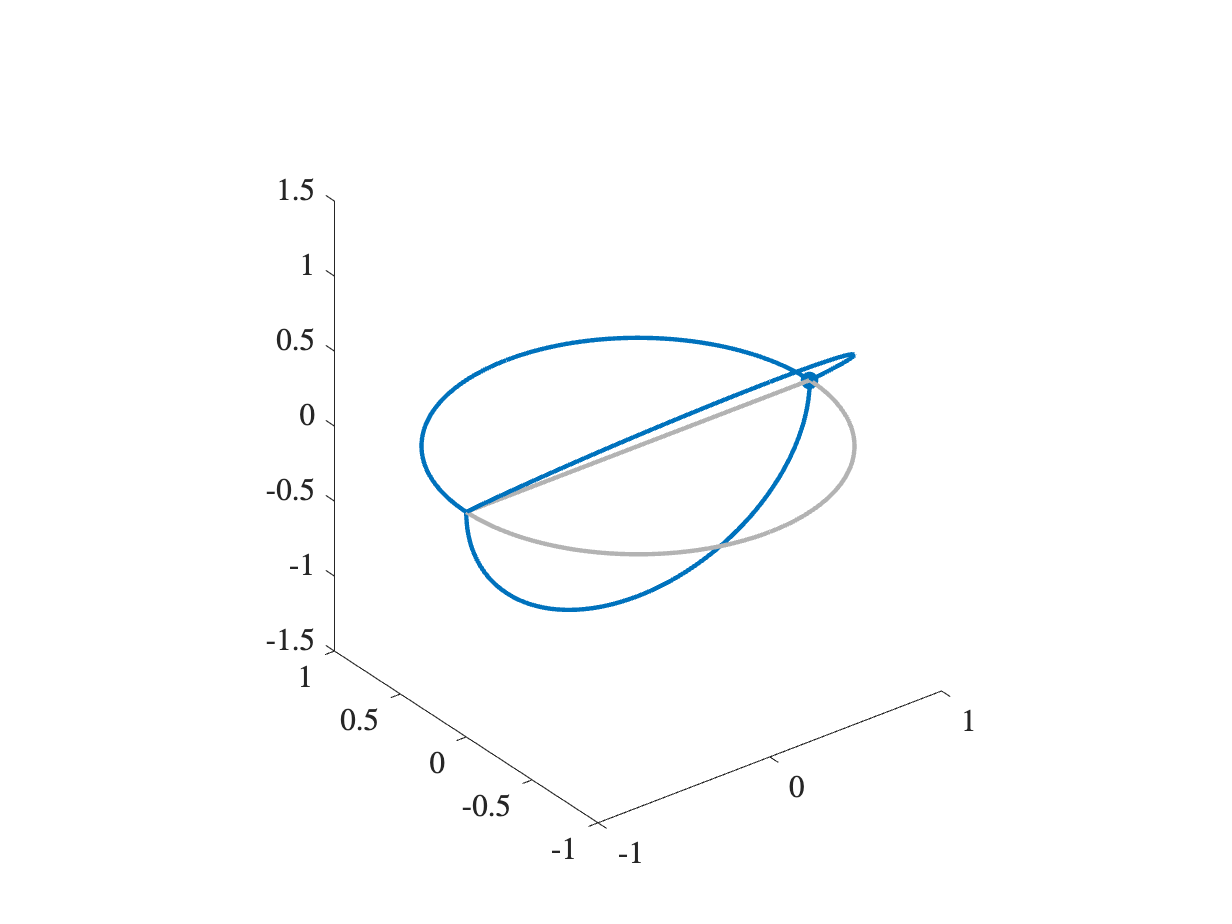

Phi.applyFunctionsToAllEdges({@sin,@(x)-sin(x),0})
Phi.plot

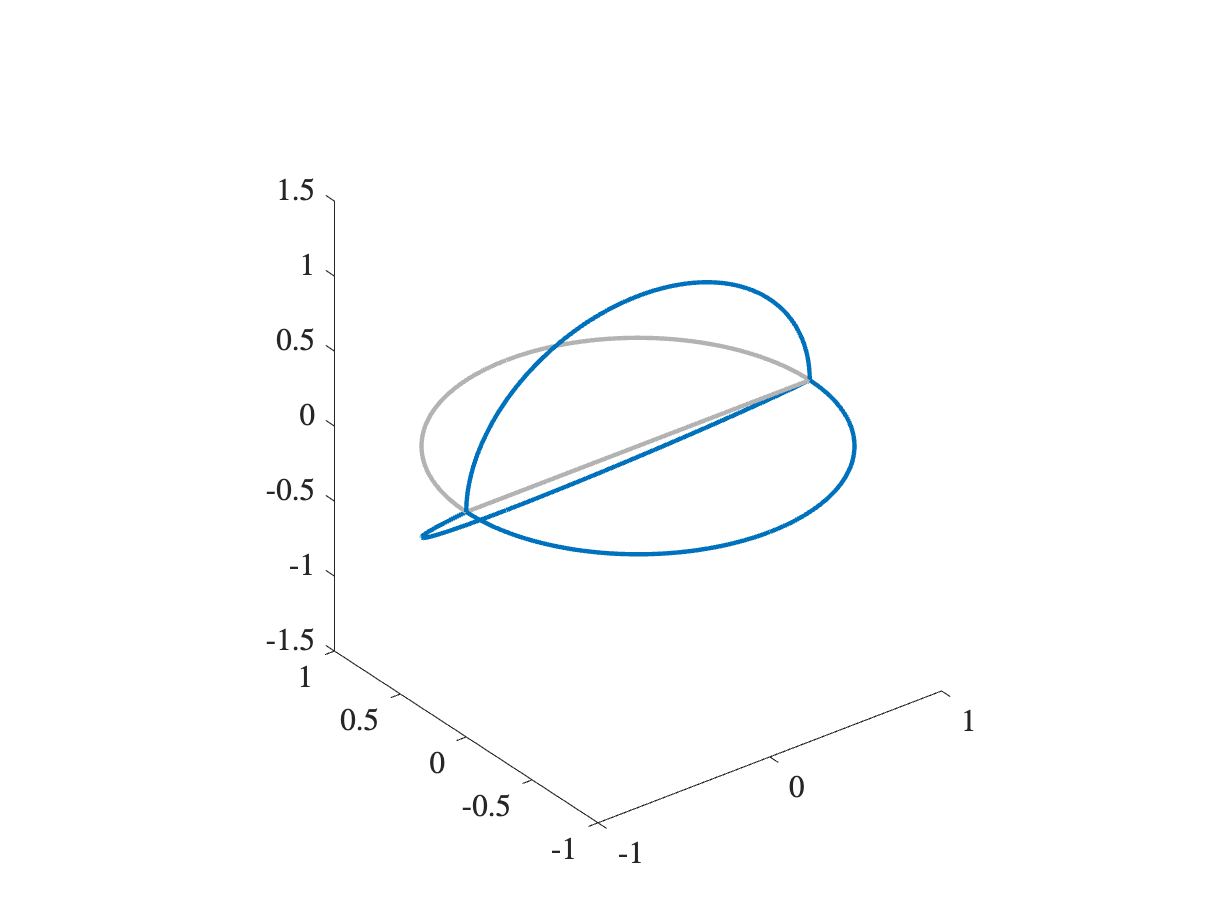

Phi.applyFunctionsToAllEdges({0,@sin,@(x)-sin(x)})
Phi.plot

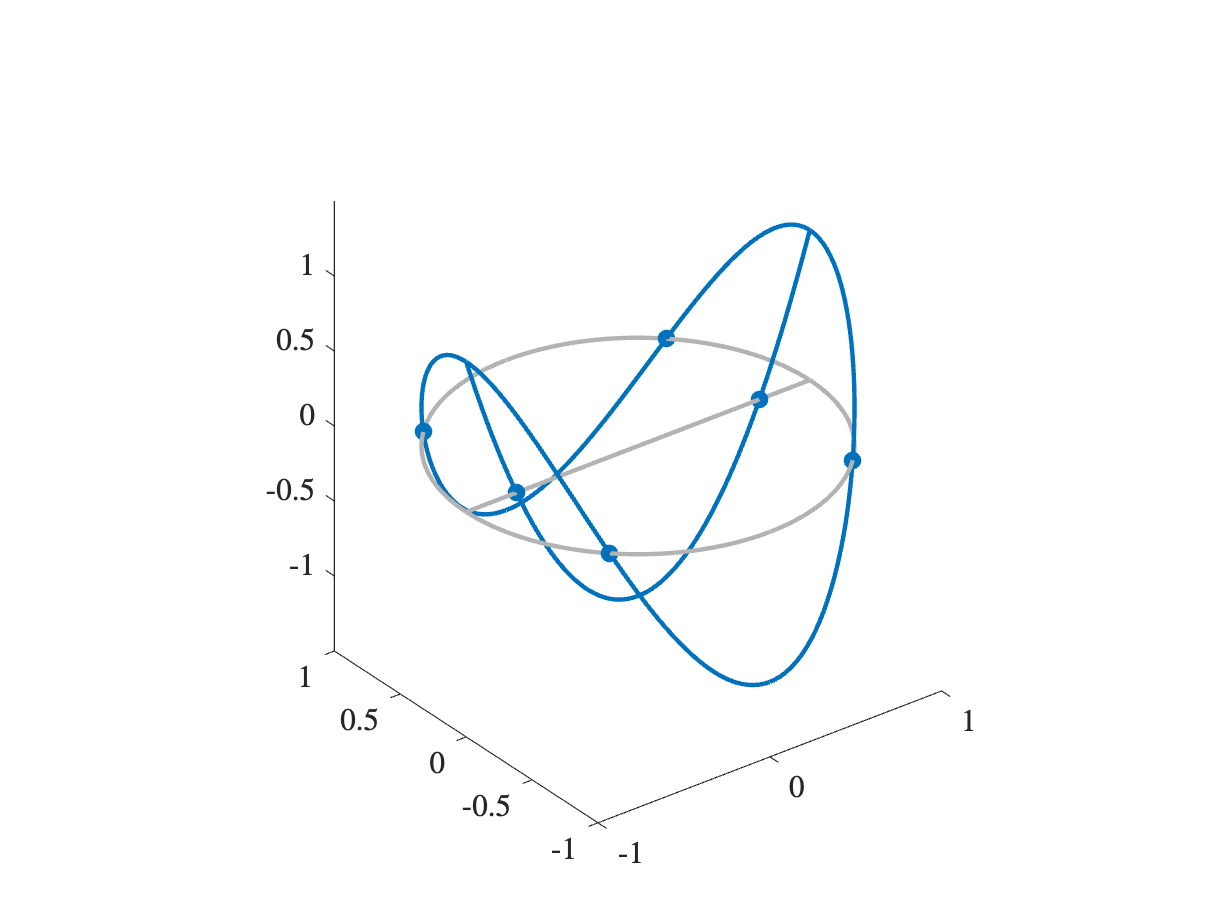

Phi.applyFunctionsToAllEdges({@(x)cos(2*x),@(x)cos(2*x),@(x)cos(2*x)})
Phi.plot

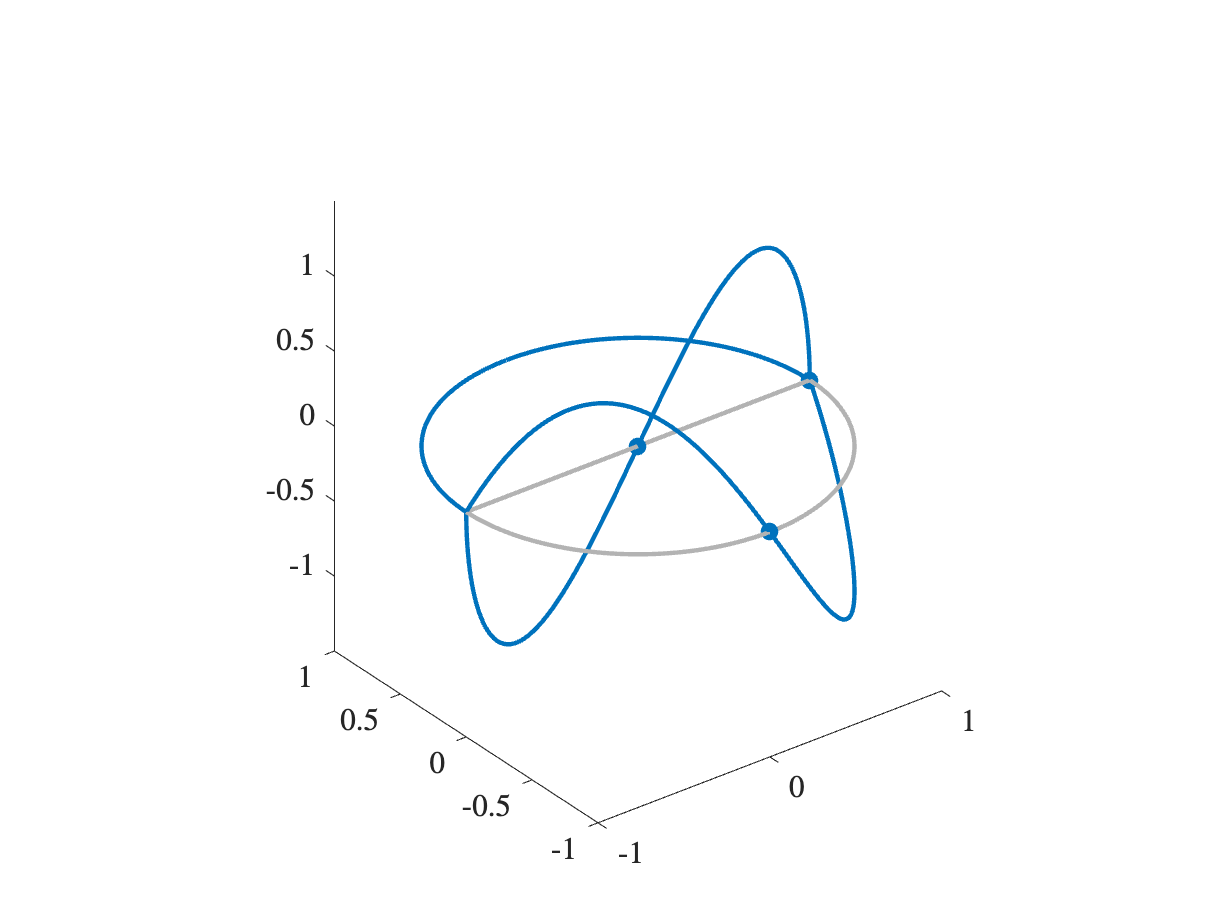

Phi.applyFunctionsToAllEdges({@(x)sin(2*x),@(x)-sin(2*x),0})
Phi.plot

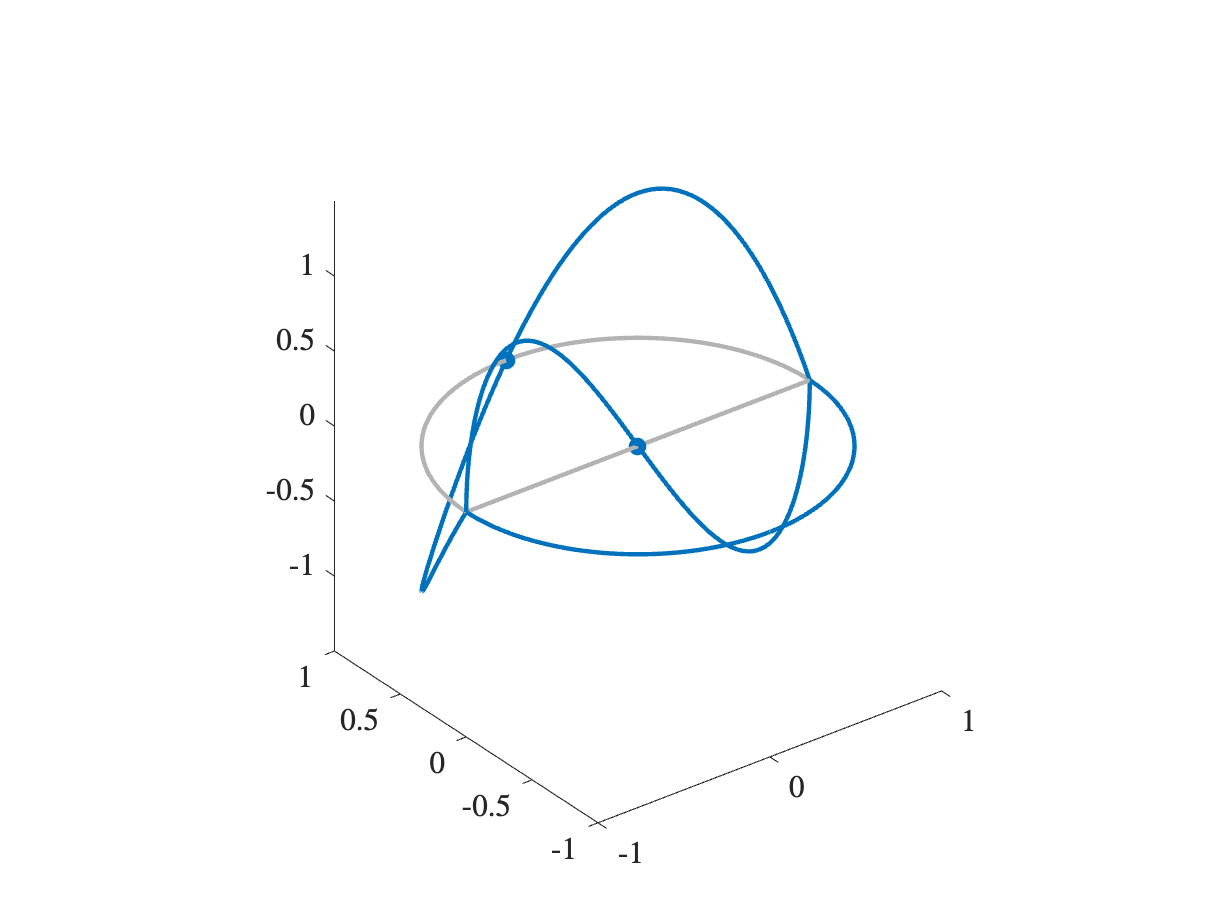

Phi.applyFunctionsToAllEdges({0,@(x)sin(2*x),@(x)-sin(2*x)})
Phi.plot